1.  Label Data

materials = {'MOFs', 'P14AQ-CNT', 'Branched PEI', 'Branched PPI' , 'Linear PEI', 'Linear PPI' , 'Piperazine', '30 wt% MEA'};
min_energies = [30, 37, 103, 102, 75, 83, 74.4, 173];
max_energies = [50, 50, 111, 106, 77, 99, 74.4, 173];

2. Sort Data

[sorted_min, sort_idx] = sort(min_energies, 'ascend'); % Sorting by min_energies

% Apply the sorting index to the max_energies
sorted_max = max_energies(sort_idx);
sorted_materials = materials(sort_idx);
% Verify each range is ordered consistently with the sorted minima
sorted_min = min(sorted_min, sorted_max);
sorted_max = max(sorted_min, sorted_max);
% Regenerate y_positions based on the length of the data
y_positions = 1:length(sorted_materials);


3. Figure Setup

figure;
hold on;

% Loop through the SORTED data and draw a thick line for each range
for i = 1:length(y_positions)
    % If min and max are the same, plot a single marker
    if sorted_min(i) == sorted_max(i)
        plot(sorted_min(i), y_positions(i), 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
    else
        % Plot the range as a thick line
        plot([sorted_min(i), sorted_max(i)], [y_positions(i), y_positions(i)], 'b-', 'LineWidth', 8);
    end
end


5. Format Axes & Labels

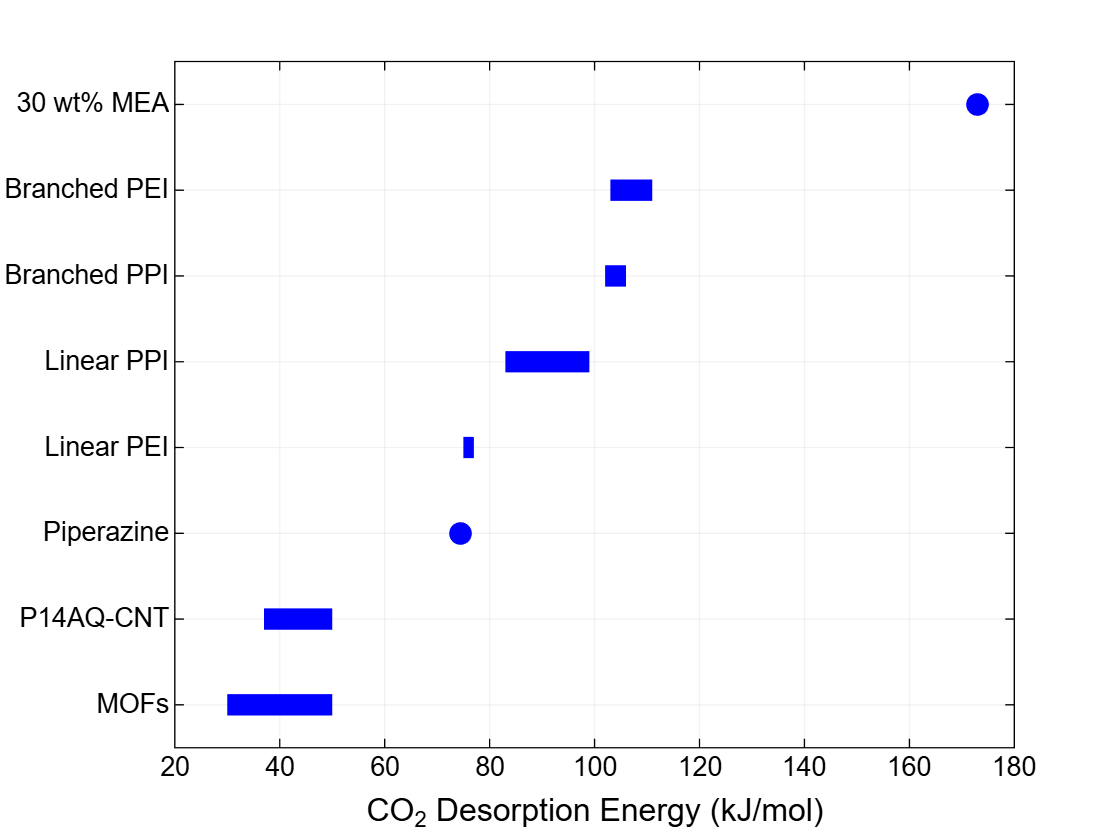

yticks(y_positions);
yticklabels(sorted_materials);
xlabel('CO_2 Desorption Energy (kJ/mol)', 'FontSize', 12);
grid on;
box on;
ylim([0.5, length(y_positions) + 0.5]);

fig = gcf;
fig.Color = 'w';

ax = gca;
ax.Color = 'w';
ax.XColor = 'k';
ax.YColor = 'k';
ax.GridColor = [0.8 0.8 0.8];

hold off;